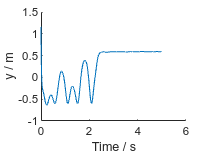

% Set simulation params
initial_angle=pi/2;  % Initial angle from vertical (radians)
sim_steps = 500;
dt = 0.01;
t = [0:dt:dt*(sim_steps-1)]';
ez0 = sin(initial_angle);
ex0 = cos(initial_angle);

initial_state = [sin(initial_angle),cos(initial_angle),sin(initial_angle), cos(initial_angle), ex0,ez0,0,0,0,0]';
initial_action = [0.0];
state = dynamics(cat(1, initial_state, initial_action));

% Initialise plotting variables
rollout_phi = zeros(sim_steps,1);
rollout_x = zeros(sim_steps, 1);
rollout_y = zeros(sim_steps, 1);
% Set initial state
rollout_phi(1) = atan2(state(1),state(2));
rollout_x(1) = state(2);
rollout_y(1) = state(3);

% Perform rollout
for sim_step=2:sim_steps
    action = evaluatePolicy(state);
    state = dynamics(cat(1,state,action));
    rollout_phi(sim_step) = atan2(state(1),state(2));
    rollout_x(sim_step) = state(5);
    rollout_y(sim_step) = state(6);
end

% Plot y coordinate
clf;
hold on;
plot(t,rollout_y)
xlabel("Time / s");
ylabel("y / m");
hold off;

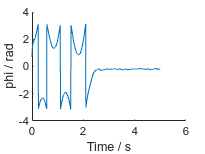


% Plot phi
clf;
hold on;
plot(t,rollout_phi)
xlabel("Time / s");
ylabel("phi / rad");
hold off;